# WindRose

**Overview**

The `WindRose` chart displays the distribution and intensities of a windspeed values, arranged by the corresponding wind directions. It is similar to a histogram or stacked bar chart, except that the data is shown in a circular (rather than linear) display, enabling easy recognition of important wind directions. The radial values in the chart represent the percentage of observations falling into each combined speed/direction bin. 

The chart data comprises a table `WindData` containing two variables:

- a nonnegative numeric vector `Speed`, and 

- a numeric vector `Direction` (taking values between 0 and 360 degrees). 

To create the graphics, the chart performs binning on the windspeed and wind direction data, similar to the 2D binning performed by [histcounts2](matlab: doc("histcounts2")). However, due to the need to wrap directions correctly at 360°, the chart bins the observations lying in each wind direction interval separately using [histcounts](matlab: doc("histcounts")). The binning process is as follows.

- The speed data is divided into bins, using the chart parameter `SpeedBinEdges`. This is a strictly increasing vector of the form $\mathbf{e}=[0, v_1, v_2, \dots, v_n, \infty]$, where $v_i<v_{i+1}$ for $i=1, 2, \dots, n-1$. The first and last elements of $\mathbf{e}$ are 0 and $\infty$, respectively, to ensure that all windspeeds present in the data set are included in the wind rose.

- The direction data is divided into 36 bins of equal angular size (10 degrees).

- The chart property `ObservationCounts` contains the number of observations in each speed-direction bin. These counts are also converted to percentages and accumulated in the speed direction for display in the wind rose.

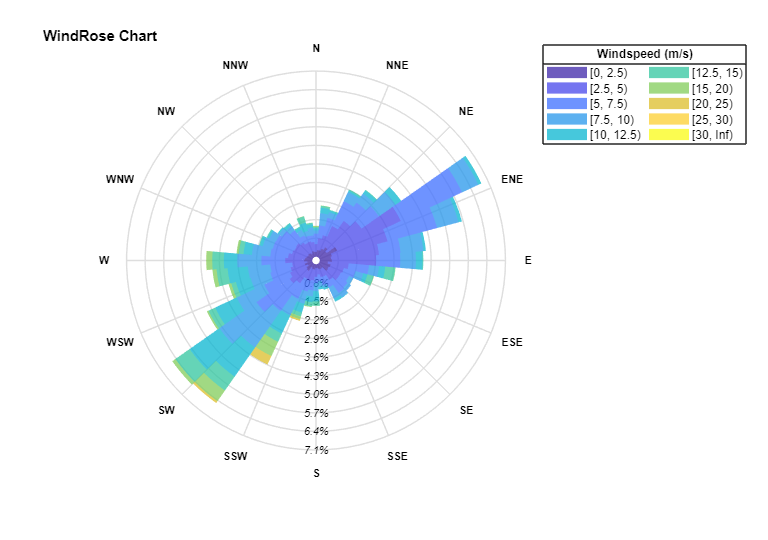

**Resources**

[Open](matlab: edit(fullfile(catalogRoot(), "+example", "WindRose.mlx"))) this Live Script to run and interact with the examples shown below.

[View](matlab: edit(fullfile(catalogRoot(), "+chart", "WindRose.m"))) the source code for the `WindRose` chart.

Documentation for:

- [histcounts](matlab: doc("histcounts")): histogram bin counts

- [histcounts2](matlab: doc("histcounts2")): bivariate histogram bin counts

- [patch](matlab: doc("patch")): plot one or more filled polygonal regions

## Load the observed wind data.

The data comprises a 2-column table with wind speed and wind direction measurements.

load( fullfile( catalogRoot(), "data", "Wind.mat" ) )

Display a preview of the data table.

disp( head( W ) )

    Direction    Speed 
    _________    ______

      252.9       8.512
      260.9      8.5753
        258      10.474
      246.7      9.3895
      255.3      10.468
      259.6      9.8207
      266.8      8.8305
      263.7      6.3923



## Create a figure for the chart.

f = exampleFigure( "Name", "Wind Rose Example", ...
    "Color", "w" );

## Create the chart.

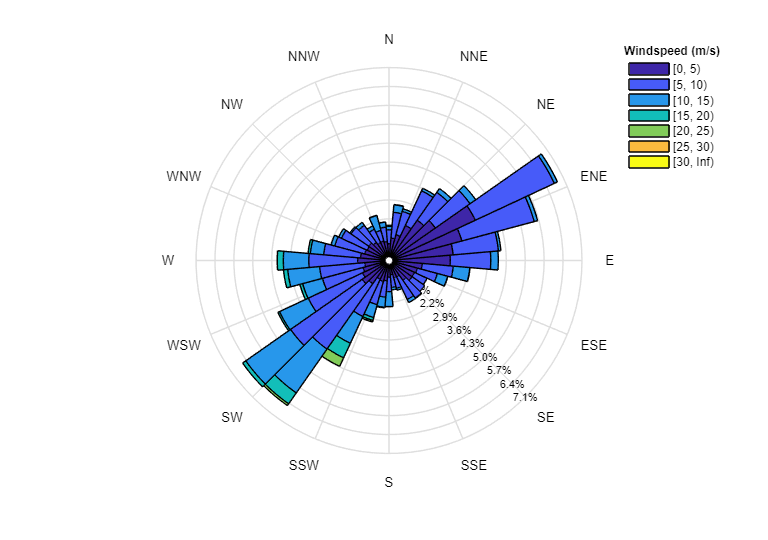

WR = chart.WindRose( "Parent", f, ...
    "WindData", W );

## Annotate the chart.

The `WindRose` chart has the `title` method for annotation.

title( WR, "WindRose Chart" )

The legend is managed by the chart, and the chart provides a large number of legend-related properties for customizing the legend appearance.

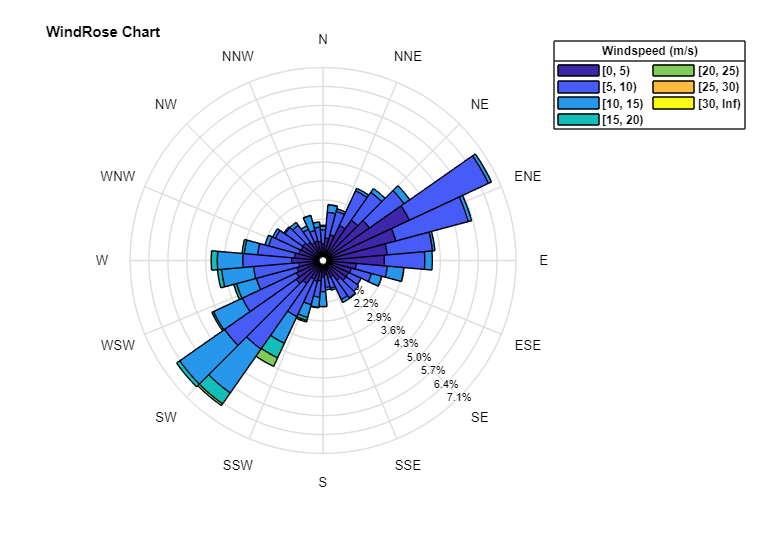

set( WR, "LegendBox", "on", ...
    "LegendFontWeight", "bold", ...
    "LegendNumColumns", 2 )

## Modify the windspeed bins.

We can adjust the bins used to discretize the windspeed values. For example, we might want to use more bins in the lower range of windspeeds.

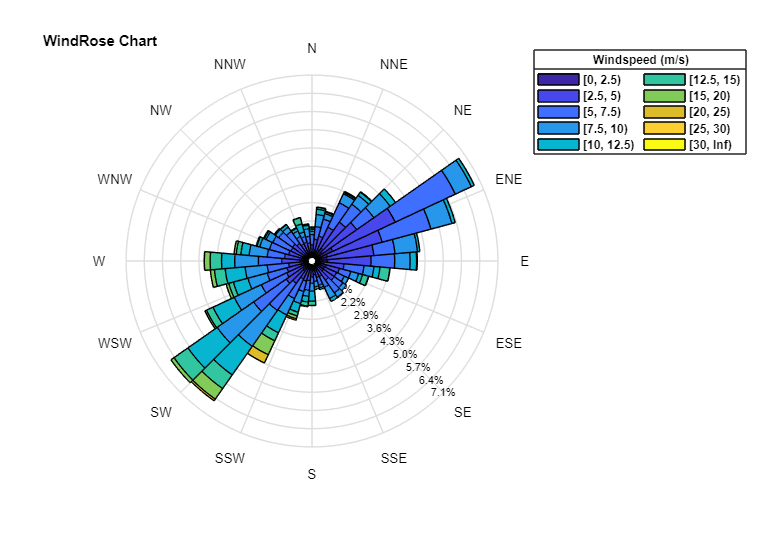

WR.SpeedBinEdges = [0:2.5:15, 20:5:30, Inf];
drawnow()

## Adjust the appearance of the polar histogram.

The polar histogram is built from `patch` objects, and the chart exposes several of their decorative properties for customization purposes.

Change the colormap used by the chart.

numSpeedBins = length( WR.SpeedBinEdges ) - 1;
WR.FaceColors = cool( numSpeedBins );

Modify the patches.

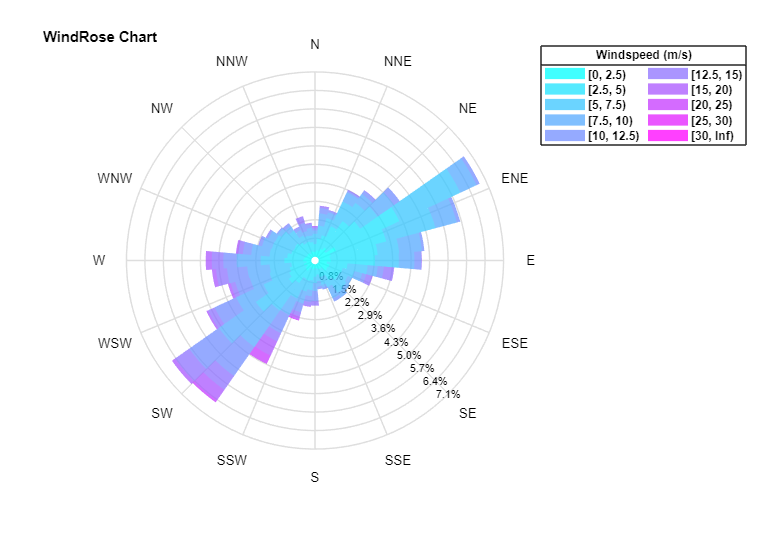

set( WR, "FaceAlpha", 0.75, "EdgeColor", "none" )

## Customize the chart's text objects.

The chart manages both the radial percentage labels and the wind direction labels. We can customize their appearance as required.

For example, we can change the wind direction along which the radial labels are displayed.

WR.RadialLabelDirection = "S";

The direction labels can be moved in and out using the `DirectionLabelOffset` property.

WR.DirectionLabelOffset = WR.DirectionLabelOffset - 0.1;

There are also a number of decorative properties.

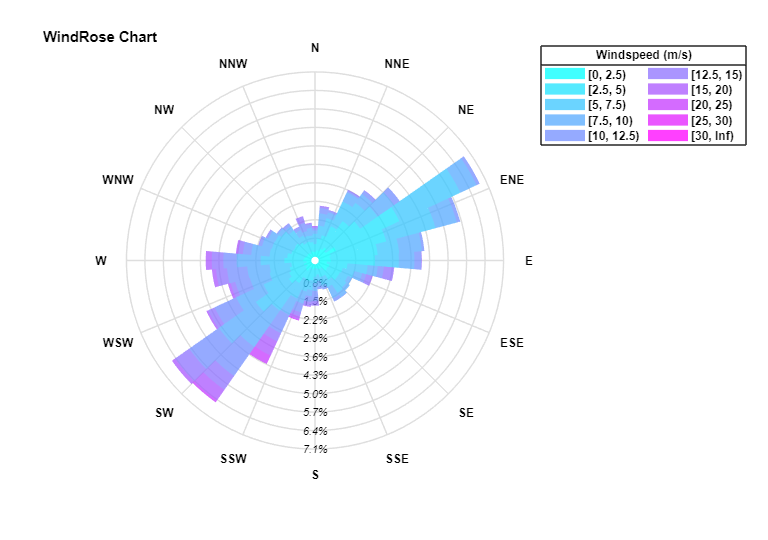

set( WR, "DirectionLabelFontSize", 9, ...
    "DirectionLabelFontWeight", "bold", ...
    "RadialLabelFontAngle", "italic" )

## Reduce the chart data.

Take the first 500 samples from the data table.

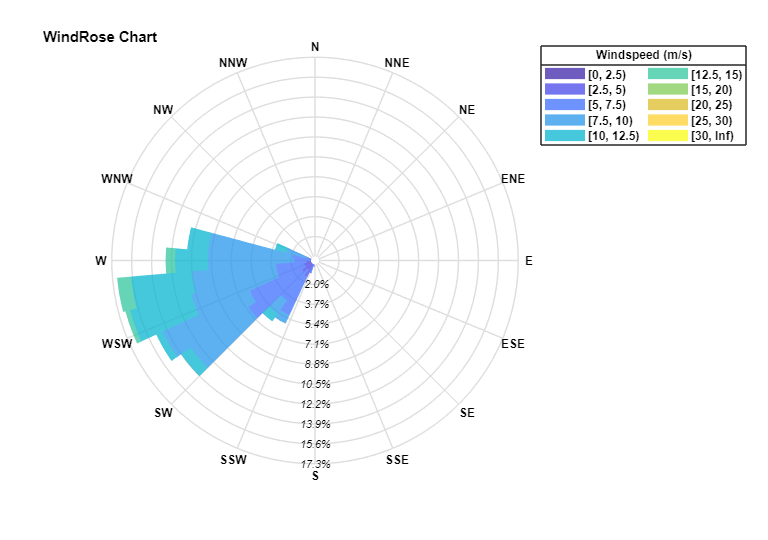

WR.WindData = W(1:500, :);

## Reset the chart data to the original table.

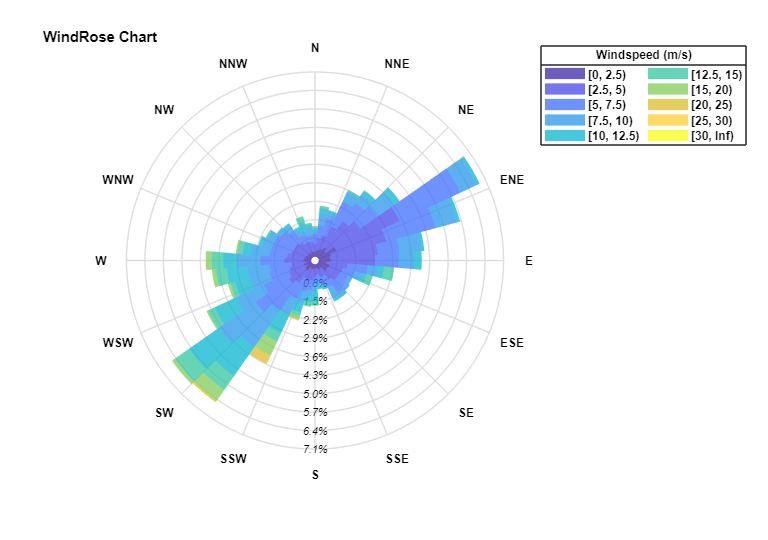

WR.WindData = W;

## Chart interactivity.

The patches making up the polar histogram are interactive. When the user clicks on a patch, a text box containing information on the speed-direction bin appears. Clicking again hides the text box.

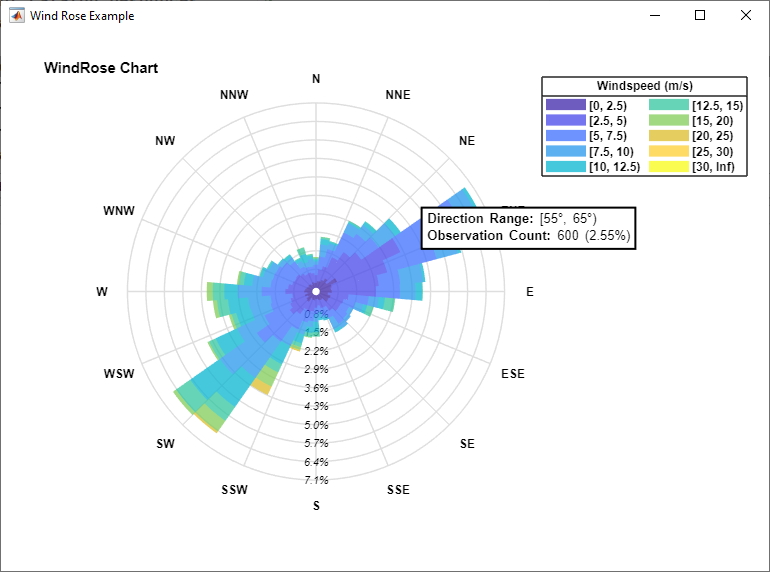

*Copyright 2018-2021 The MathWorks, Inc.*